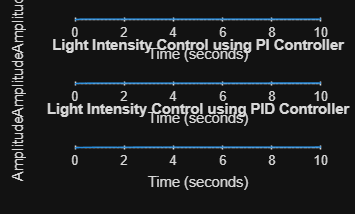

clc;
clear;
close all;

% Plant Model (Lamp + Sensor)
K = 1;
tau = 0.5;

num = [K];
den = [tau 1];

plant = tf(num,den);

% Time vector
t = 0:0.01:10;

%% P Controller
Kp = 5;
Gc_P = pid(Kp);

sys_P = feedback(Gc_P*plant,1);

%% PI Controller
Kp = 5;
Ki = 2;

Gc_PI = pid(Kp,Ki);

sys_PI = feedback(Gc_PI*plant,1);

%% PID Controller
Kp = 5;
Ki = 2;
Kd = 0.5;

Gc_PID = pid(Kp,Ki,Kd);

sys_PID = feedback(Gc_PID*plant,1);

%% Step Responses
figure;

subplot(3,1,1)
step(sys_P,t)
grid on
title('Light Intensity Control using P Controller')

subplot(3,1,2)
step(sys_PI,t)
grid on
title('Light Intensity Control using PI Controller')

subplot(3,1,3)
step(sys_PID,t)
grid on
title('Light Intensity Control using PID Controller')

stepinfo(sys_P)

ans = struct with fields:
         RiseTime: 0.1831
    TransientTime: 0.3260
     SettlingTime: 0.3260
      SettlingMin: 0.7538
      SettlingMax: 0.8328
        Overshoot: 0
       Undershoot: 0
             Peak: 0.8328
         PeakTime: 0.6102


stepinfo(sys_PI)

ans = struct with fields:
         RiseTime: 1.1011
    TransientTime: 5.8020
     SettlingTime: 5.8020
      SettlingMin: 0.9001
      SettlingMax: 0.9980
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9980
         PeakTime: 12.5550


stepinfo(sys_PID)

ans = struct with fields:
         RiseTime: 1.2546
    TransientTime: 7.7463
     SettlingTime: 5.7896
      SettlingMin: 0.9001
      SettlingMax: 0.9994
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9994
         PeakTime: 15.4818
